## Taylor Series Approximation

The Taylor series allows us to approximate a function using a polynomial.

Taylor series lets us replace a difficult function with a simple polynomial. Computers are very good at evaluating polynomials.

A Taylor approximation is only guaranteed to be accurate near the point where it is constructed.

For a function $f$ at $x = a$, the Taylor approximation is


$$f(x)\approx f(a) + f'(a)(x-a) + \frac{f''(a)}{2!}(x-a)^2 + \frac{f'''(a)}{3!}(x-a)^3 +\cdots$$


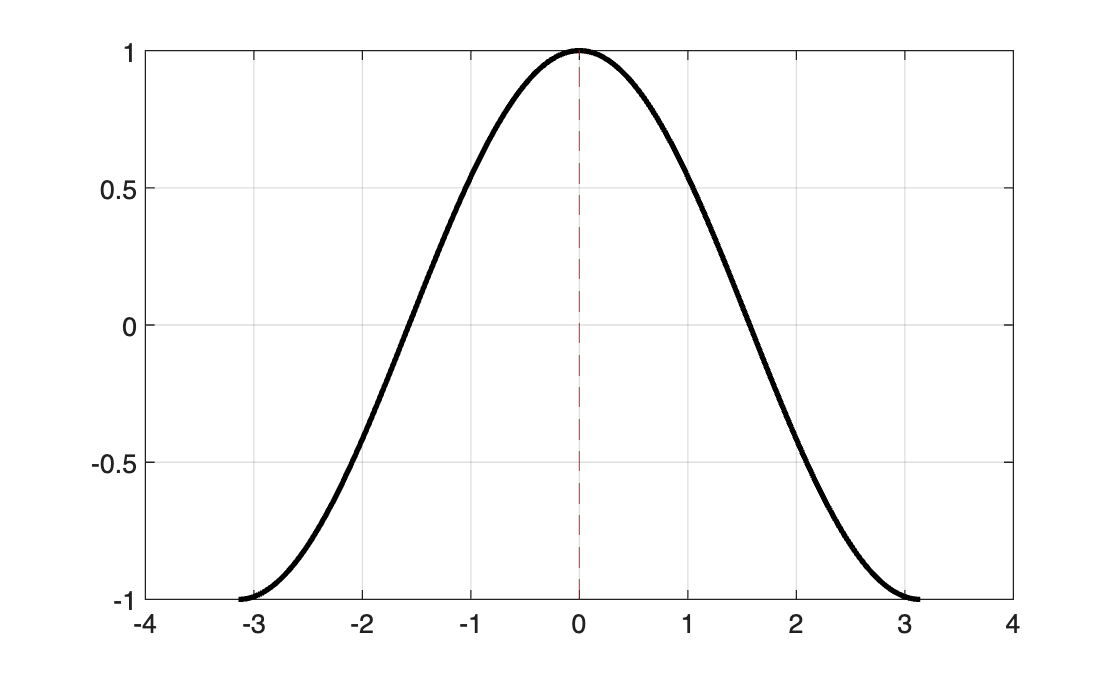

f = @(x) cos(x);

% Take 1000 points between -π to π
x = linspace(-pi, pi,1000);

plot(x,f(x),'k','LineWidth',2)
hold on

% Our goal will be to approximate *around* x = 0
xline(0,'--r')
grid on

### First Approximation

The first term for the Taylor expansion of $\cos(x)$ at x = 0 is simply $\cos(0) = 1$

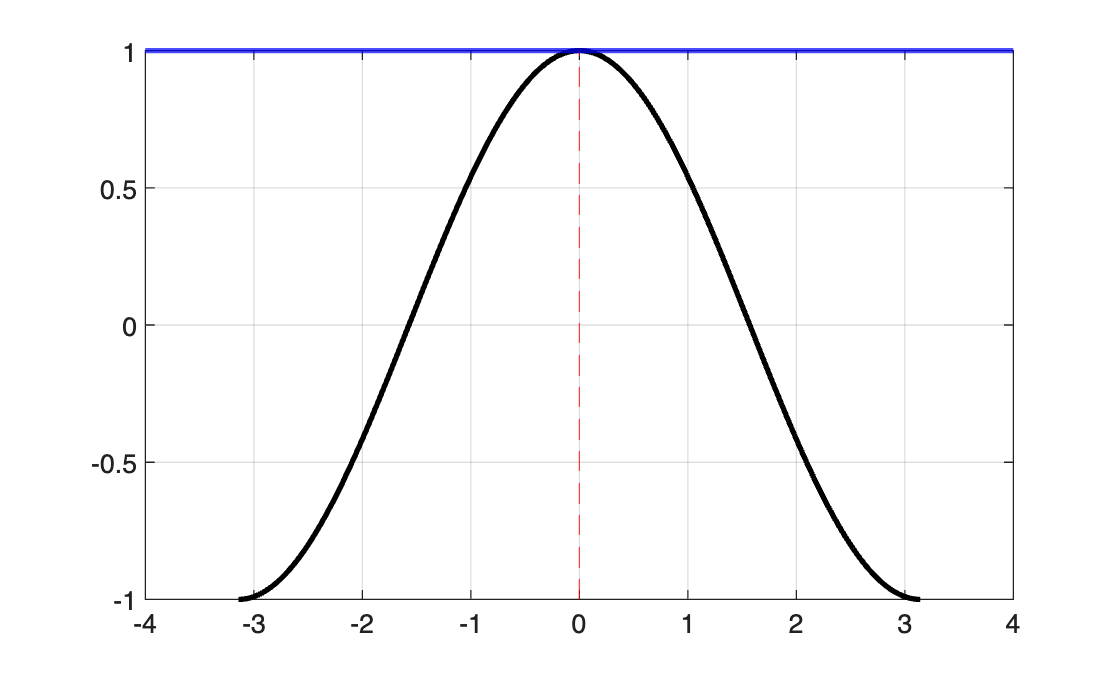

yline(1, '-b', 'LineWidth', 2)

### Second approximation

The second term of the Taylor series in this case is 0 (since it has a $\sin(0)$ term, and that's just 0). So we move to the next term in the series, which turns out to be $\frac{-x^2\cos(0)}{2} = - \frac{x^2}{2}$ 

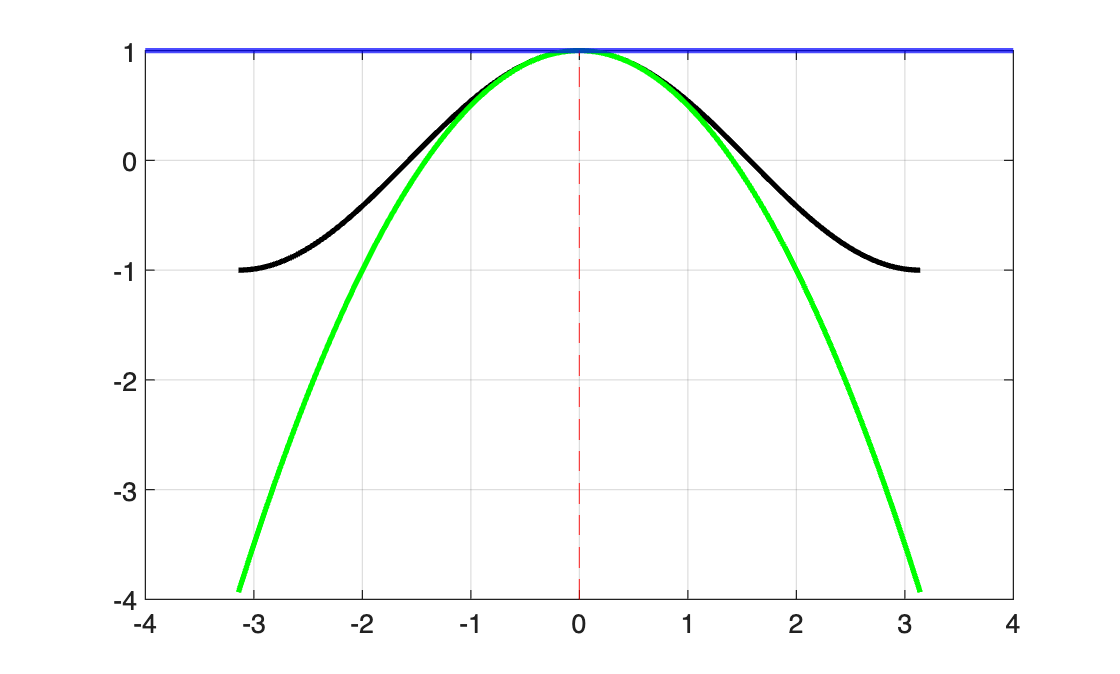

T2 = @ (x) - x.^2 / 2;
plot (x, 1 + T2(x), 'g', 'LineWidth', 2)

### Adding another term!

The next term turns out to be $\frac{x^4}{24}$ 

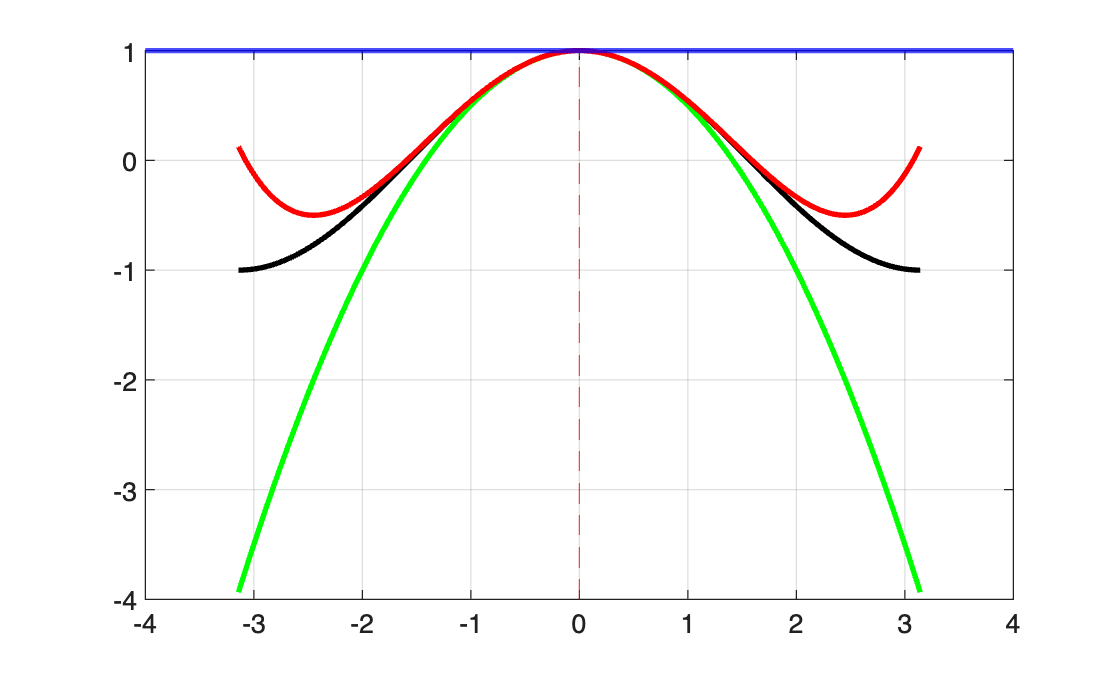

T3 = @ (x) x.^4 / 24;
plot (x, 1 + T2(x) + T3(x), 'r', 'LineWidth', 2)